% Number 1; n = 20
% Summation of incrementing alternating numbers
result = 0;
input = 20;
for i = 1:input
    result = result + i*((-1)^i);
end
result

result = 10


% Number 2; n = 100
% Summation of incrementing alternating numbers
result = 0;
input = 100;
for i = 1:input
    result = result + i*((-1)^i);
end
result

result = 50

% Number 2; long format
f = @(x) 0.5*(x-1).^2;
format long;

f(sqrt(3))

ans =    0.267949192431123


% Longs hold more places (15)
% 0.267949192431123

%Number 2; short format
format short;

f(sqrt(3))

ans = 0.2679

% Shorts hold 4 places
% 0.2679

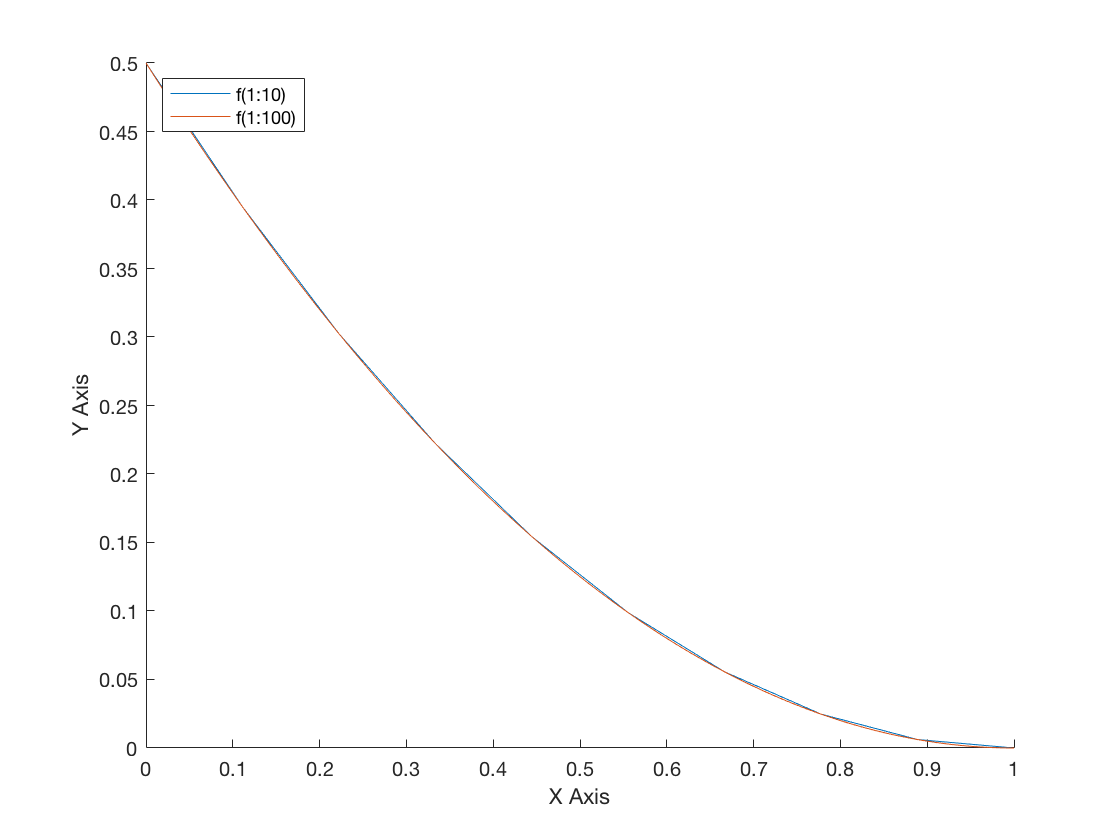

%Number 3 Plotting both functions on same graph
%The line with fewer elements will look more jagged
f = @(x) 0.5*(x-1).^2;
t = linspace(0,1,10);
t2 = linspace(0,1,100);
hold on
plot(t,f(t))
plot(t2,f(t2))
legend({'f(1:10)','f(1:100)'},'Location','northwest');
xlabel("X Axis");
ylabel("Y Axis");
hold off

% Number 4
% differential equation as
% an anonymous function
h = @(x,h)(f(x+h)-f(x))/h;

h(1.1,0.1)

ans = 0.1500

h(1.1,0.01)

ans = 0.1050

h(1.1,0.001)

ans = 0.1005

%Number 5
t = linspace(0,2,100);
line = @(m,x) m*(x-1.1) + 0.005  

line = function_handle with value:
    @(m,x)m*(x-1.1)+0.005


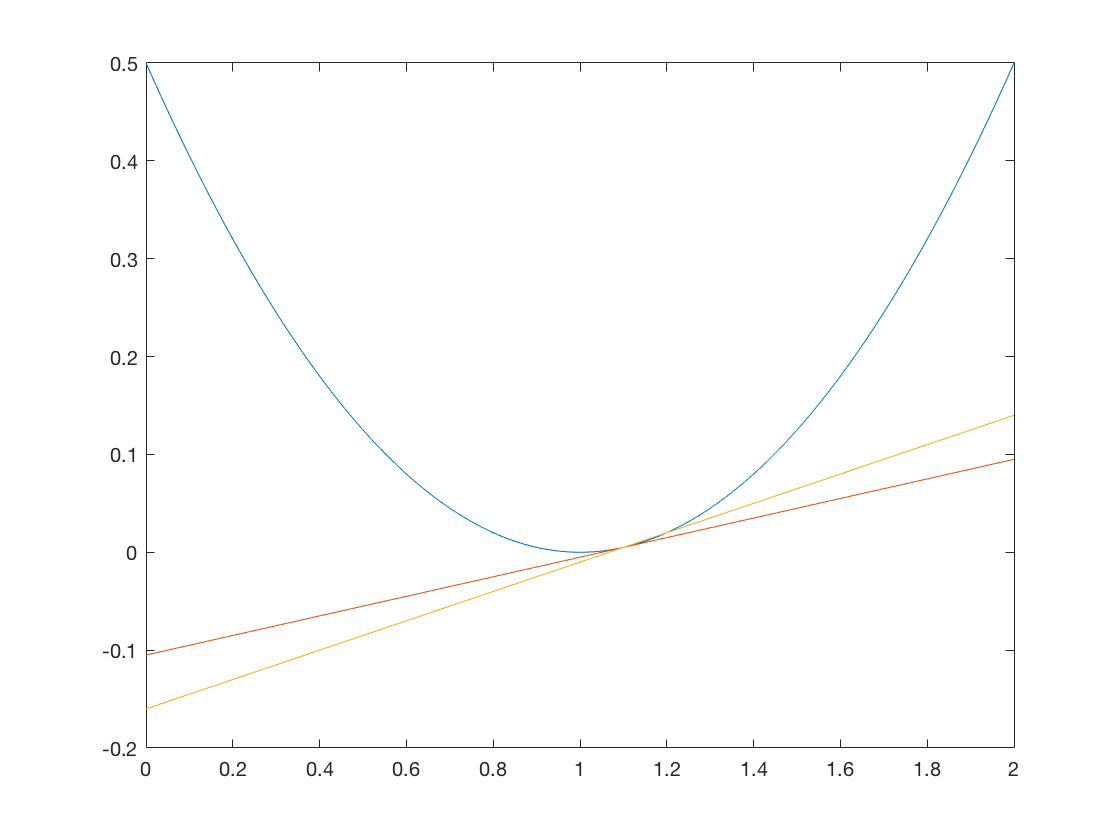


%Plots all 3 functions
plot(t,f(t),t,line(.1,t),t,line(h(1.1,0.1),t))

%Functions used
f = @(x) 0.5*(x-1).^2; % Original Equation
h = @(x,h)(f(x+h)-f(x))/h; % Differential Equation